# Interpolación

## Interpolación polinomial

Sean $(x_0,y_0),(x_1,y_1),...,(x_n,y_n),n+1$ puntos con predictores distintos y respuestas $y_i$. Deseamos hallar un polinomio$P(t)=c_nt^n+c_{n-1}t^{n-1}+...+c_1t+c_0$ que interpole los $n+1$ puntos, es decir $P(x_i)=y_i$, equivalente a hallar los coeficientes $c_i$ que satisfagan el sistema lineal 


$$c_nx_0^n+c_{n-1}x_0^{n-1}+\cdots+c_1x_0+c_0=y_0\\
c_nx_1^n+c_{n-1}x_1^{n-1}+\cdots+c_1x_1+c_0=y_1\\
\ \cdots\ \ \ \cdots\ \ \cdots\ \ \cdots\ \ \cdots \ \ \cdots=\cdots\\
c_nx_n^n+c_{n-1}x_n^{n-1}+\cdots+c_1x_n+c_0=y_n\\$$


## Lagrange

% graficar (puntos * rojos)
x=[1 5 20 40];
y=[56.5 113 181 214.5];
a=2;
interpolacion1(x,y,a)

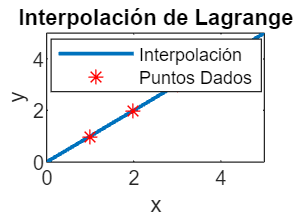

ans = 72.7254

% graficar (puntos * rojos)
x=[1 5 20 40];
y=[56.5 113 181 214.5];
a=2;
Lagrange(x,y,a)

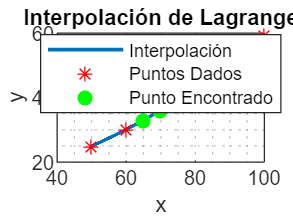

Pa =    32.9795   36.0500


T=50:10:100;
P=[24.94 30.11 36.05 42.84 50.57 59.30];
a=64;
Pa=Lagrange2(T,P,[65 70])

c=[4 12 20 28];
T=[0 40 80 100];
d=[1.0381 1.0276 1.0063 0.9931;
   1.1160 1.1013 1.0786 1.0663;
   1.1977 1.1801 1.1570 1.1451;
   1.2846 1.2652 1.2418 1.2301]

d =     1.0381    1.0276    1.0063    0.9931
    1.1160    1.1013    1.0786    1.0663
    1.1977    1.1801    1.1570    1.1451
    1.2846    1.2652    1.2418    1.2301


d(4,1:end)

ans =     1.2846    1.2652    1.2418    1.2301


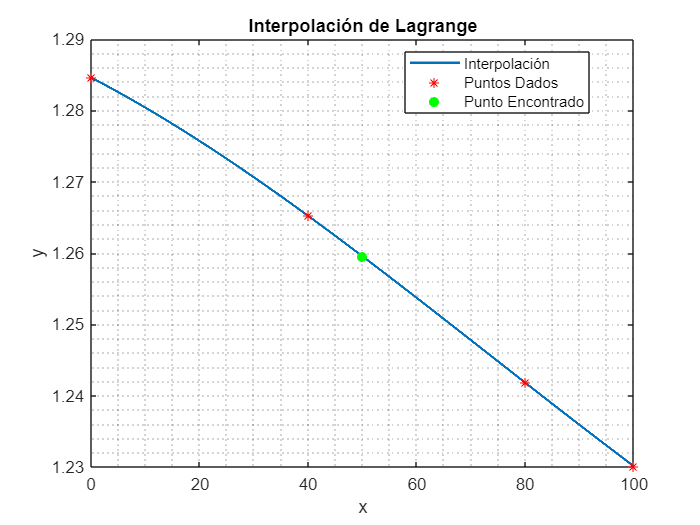

Pa = 1.2595

Pa=Lagrange2(T,d(4,1:end),50)

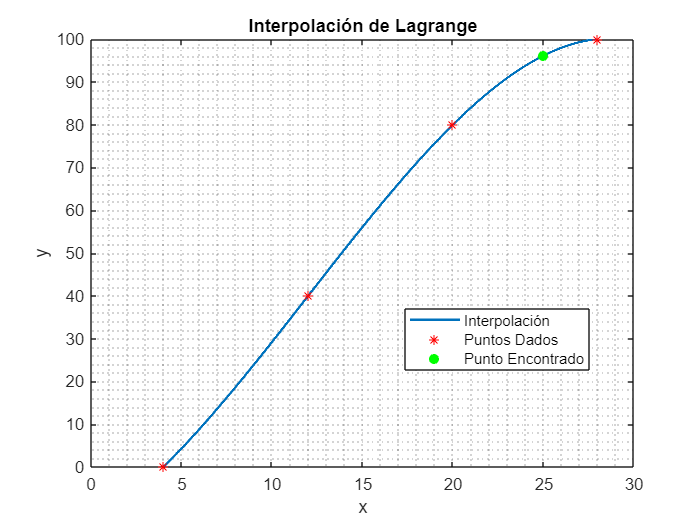

Pa = 96.1133

Pa=Lagrange2(c,T,25)

## Aproximación por mínimos cuadrados

Supongamos que tenemos n puntos $(x_1,y_1),(x_2,y_2),...,(x_n,y_n)$ donde $x_i$ son los predictores y $y_i$ son respuestas

Y sea $y=f(x)$ una función de ajuste deseamos minimizar la función error que se define como $MSE=\sum_{i=1}^{n}(f(x_i)-y_i)^2$ (se utiliza el cuadrado en vez de el valor absoluto ya que cuenta con un punto no derivable)

Para el caso especial de una regresión lineal donde $f(x)=y=mx+b$ entonces$\sum_{i=1}^{n}(mx_i+b-y_i)^2$

Se busca minimizar por medio de derivadas parciales igualadas a cero respecto a m y b

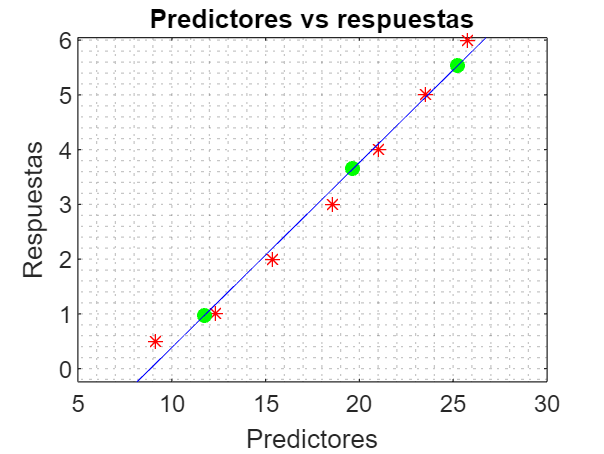

El valor del predictor 19.65        11.73        25.25 es: 3.6464     0.96765      5.5405


P =    0.338228852050815  -2.999779322883558


format long
c=[0.5 1 2 3 4 5 6]; % concentraciones
n=[9.15 12.35 15.35 18.55 21 23.5 25.75]; % actividad óptica
nb=[19.65 11.73 25.25];
P=MinimosCuadradosRecta2(n,c,nb)

El error está dentro de la tolerancia indicada


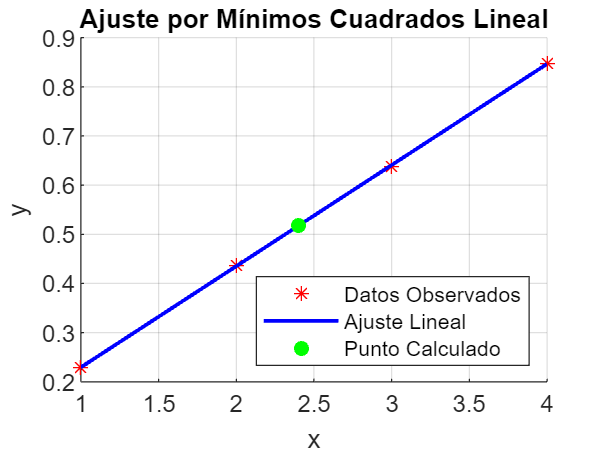

error =      1.120000000000000e-05


recta = 'y = 0.205600x + 0.024000'

x_calculado =    2.402723735408559



x = [1 2 3 4];
y = [0.230 0.436 0.638 0.848];
[error, recta, x_calculado] = ajusteMinimosCuadrados2(x,y,0.518)

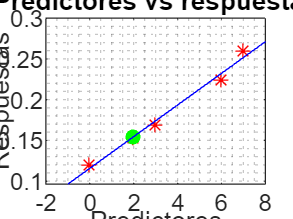

El valor del predictor 2 es: 0.15451


P =     0.0194    0.1156


F=[0 2 3 6 7];
L=[0.120 0.153 0.170 0.225 0.260];
P=MinimosCuadradosRecta2(F,L,2)

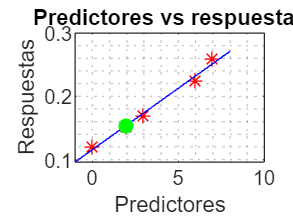

El valor del predictor 2 es: 0.15451


ans =     0.0194
    0.1156


MinimosCuadradosPolinimio(F,L,1,2)

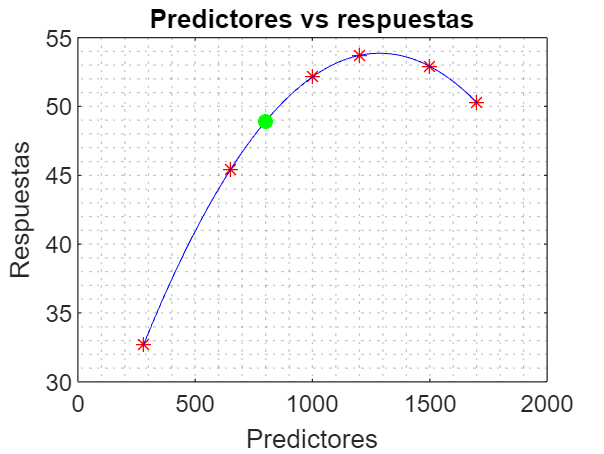

El valor del predictor 800 es: 48.9152


C =   -0.000020878734670
   0.053727701612040
  19.295435964548140


T=[280 650 1000 1200 1500 1700];
Cp=[32.7 45.4 52.15 53.7 52.9 50.3];
C=MinimosCuadradosPolinimio(T,Cp,2,800)

El error está dentro de la tolerancia indicada


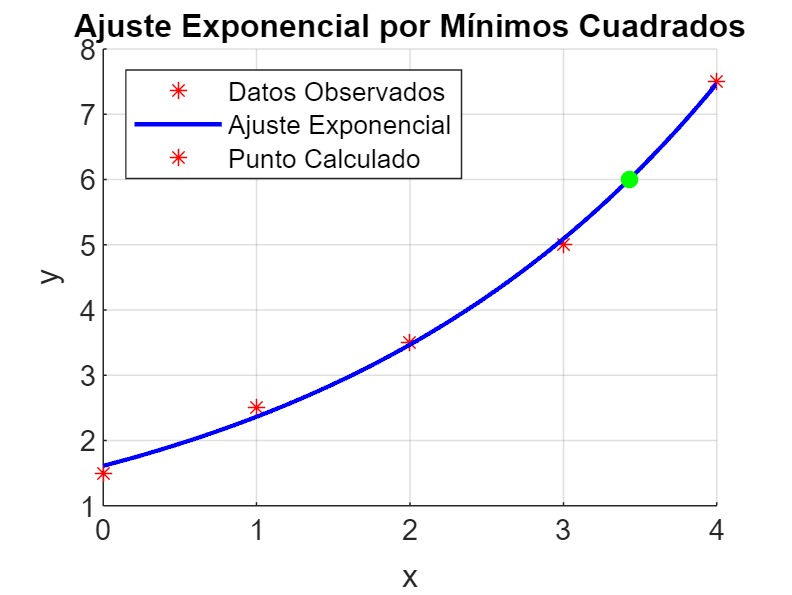

error = 0.0409

recta = 'y = 1.610869e^{0.383575x}'

x_calculado = 3.4282

x_obs=[0 1 2 3 4];
y_obs=[1.5 2.5 3.5 5 7.5];
[error,recta,x_calculado]=MinimosCuadradosExp(x_obs,y_obs,6)

El error está dentro de la tolerancia indicada


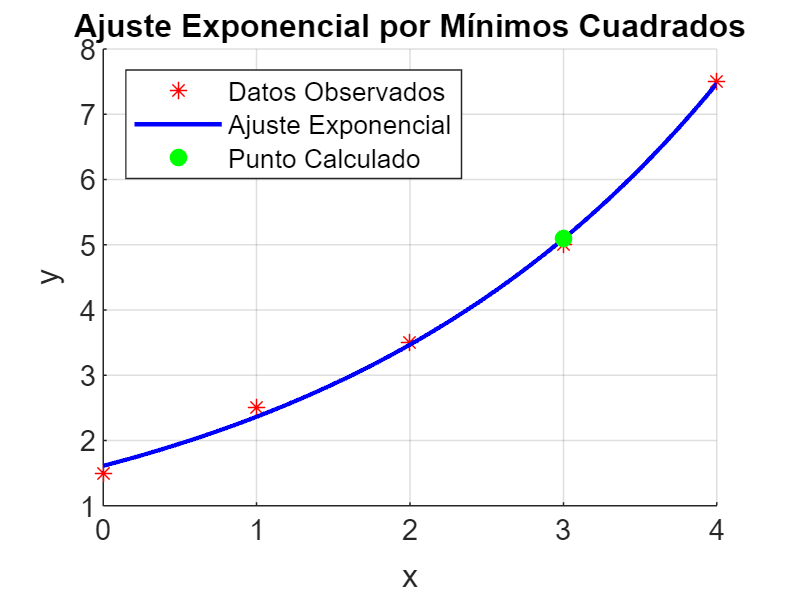

error = 0.0409

funcion = 'y = 1.610869e^{0.383575x}'

ycalc = 5.0911

[error,funcion,ycalc]=MinimosCuadradosExp2(x_obs,y_obs,3,[1 1])

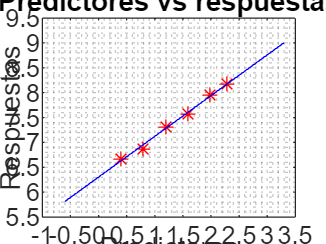

P =     0.8187    6.3037


clc; clear all;
x=[0.4 0.8 1.2 1.6 2 2.3];
y=[800 975 1500 1950 2900 3600];
X=x;
Y=log(y);
P=MinimosCuadradosRecta2(X,Y)

B=P(1)/log(10)

B = 0.3555

A=exp(P(2))

A = 546.5909

f=@(x)A*10.^(B*x)

f = function_handle with value:
    @(x)A*10.^(B*x)


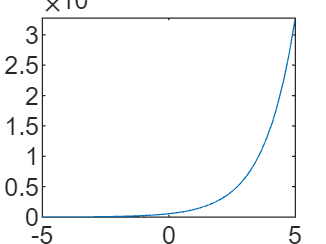

fplot(f)

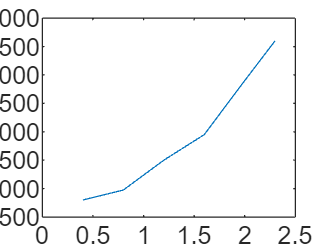

clc; clear; close all;
x=[0.4 0.8 1.2 1.6 2 2.3];
y=[800 975 1500 1950 2900 3600];
plot(x,y)

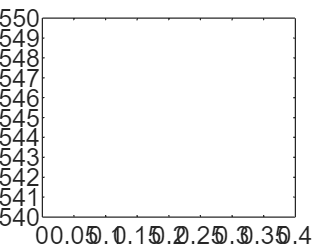

% syms A B
f1=A.*sum(10.^(2*B.*x))-sum(y.*10.^(B.*x));
f2=A.*sum(x.*10.^(2*B.*x))-sum(x.*y.*10.^(B.*x));
fimplicit(f1,[0 0.4 540 550])
hold on
fimplicit(f2,[0 0.4 540 550])
hold off

x=[0.4 0.8 1.2 1.6 2 2.3];
y=[800 975 1500 1950 2900 3600];
gradient_error=@(A,B)[A.*sum(10.^(2*B.*x))-sum(y.*10.^(B.*x)),A.*sum(x.*10.^(2*B.*x))-sum(x.*y.*10.^(B.*x))];
B=0.35;
A=546;
[sol,~]=fsolve(@(x)gradient_error(x(1),x(2)),[A B]);


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>


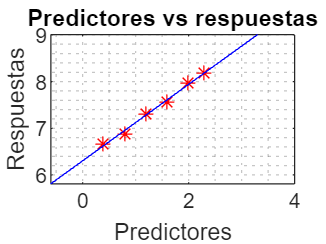

f=@(x)sol(1)*10.^(sol(2)*x);
X=x;
Y=log(y);
P=MinimosCuadradosRecta2(X,Y);

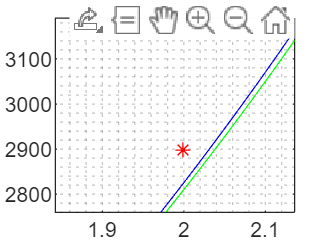

Blin=P(1)/log(10);
Alin=exp(P(2));
flin=@(x)Alin*10.^(Blin*x);
fplot(f,[0 2.5],'b')
hold on 
fplot(flin,[0 2.5],'g')
scatter(x,y,'r*');
grid minor
hold off

% clear;
% syms B
% x=[0.4 0.8 1.2 1.6 2 2.3];
% y=[800 975 1500 1950 2900 3600];
% A=sum(y.*10.^(2*B*x))/sum(10.^(2*B*x));
% f=A*sum(x.*10.^(2*B*x))-sum(x.*y.*10.^(B*x));
% fimplicit(f,[0.3 0.4])

x=[2 4 6 12 18 24];
y=[1.07 1.88 2.26 2.78 2.97 2.99];
Y=log(3-y);
[m,b]=MinimosCuadradosLinealizacion(x,Y);
a=-m

a = 0.2437

b=-log(3)

b = -1.0986


$$k=ze^{-E/1.98T}\\
\ln(k)=\ln(ze^{-E/1.98T})\\
\ln(k)=\ln(z)+\ln(e^{-E/1.98T})\\
\ln(k)=\ln(z)+(-E/1.98T)\\
\ln(k)=\frac{-E}{1.98T}+\ln(z)\\
Y=\ln(k) \ \ ,m=-E \ \ ,X=\frac{1}{1.98T} \ \ ,b=\ln(z)$$


format long
T=[293 300 320 340 360 380 400];
k=[8.53e-5 19.1e-5 1.56e-3 0.01 0.0522 0.2284 0.8631];
Y=log(k);
X=1./(1.98*T);
[m,b]=MinimosCuadradosLinealizacion(X,Y)

m =     -1.999973634186654e+04


b =   25.104478048029456


z=exp(b)

z =      7.993487263696335e+10


E=-m

E =      1.999973634186654e+04


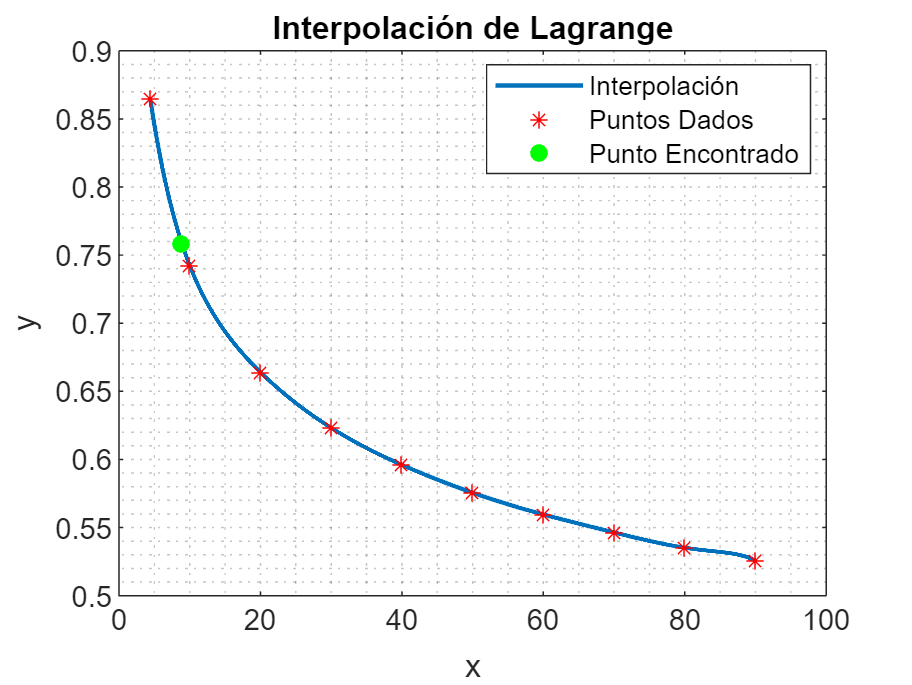

ans = 0.7587

% Integrales de colisión
k=[1.75 1.8 1.85 1.9 1.95 2 2.1 2.2 2.3 2.4 2.5 2.6 2.7 2.8 2.9 3 3.1 3.1 3.3 3.4 3.5 3.6 3.7 3.8 3.9 4 4.1 4.2 4.3 4.4 10 20 30 40 50 60 70 80 90];
diff=[1.128 1.116 1.105 1.094 1.084 1.075 1.057 1.041 1.026 1.012 0.9996 0.9878 0.9770 0.9672 0.9576 0.9490 0.9406 0.9328 0.9256 0.9186 0.9120 0.9058 0.8998 0.8942 0.8888 0.8836 0.8788 0.8740 0.8694 0.8652 0.7424 0.6640 0.6232 0.5960 0.5756 0.5596 0.5464 0.5352 0.5256];
Lagrange2(k,diff,8.88)

A='[1 2;1 3]'

A = '[1 2;1 3]'

str2double(A)

ans = NaN